lambda_pla = 0.13;
lambda_luft = 25.50 * 10^-3;
M_vand = 997;
c_vand = 4187;

l_pla = 5 * 10^-3;
l_luft = 10 * 10^-3;
H_tank = 0.1;
B_tank = 0.1;
L_tank = 0.1;
T_luft = 21;

V_tank = H_tank * B_tank * L_tank;
A_tank = H_tank * B_tank * 2 + B_tank * L_tank * 2 + L_tank * H_tank * 2;

U_pla = lambda_pla / l_pla;
U_luft = lambda_luft / l_luft;
U_tot = 1/((1/U_pla)+(1/U_luft)+(1/U_pla));

m_dej = V_tank * M_vand;
Q_dej = c_vand * m_dej;
T_dej = T_luft, zeros(1, 2*10800 - 1);

T_dej = 21

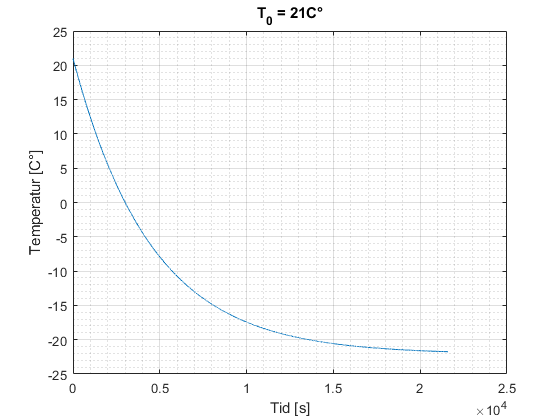


for s = 2:2*10800
    phi_tab = U_tot * A_tank * (T_luft - T_dej(s-1));
    phi_peltier = 40 - 0.8*(T_luft - T_dej (s-1));
    phi_tot = phi_peltier - phi_tab;
    T_dej(s) = T_dej(s-1) - phi_tot / Q_dej;
end
%%
plot(T_dej);
title("T_0 = 21C°")
xlabel("Tid [s]")
ylabel("Temperatur [C°]")
grid on; grid minor

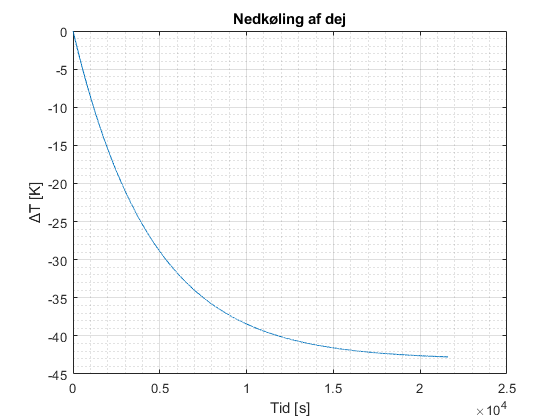

T_delta = T_dej - T_luft;

plot(T_delta)
title("Nedkøling af dej")
xlabel("Tid [s]")
ylabel("ΔT [K]")
grid on; grid minor

final_state = T_delta(end)

final_state = -42.7534

tau_T = final_state * (1 - exp(-1))

tau_T = -27.0253

tau = find(T_delta < tau_T,1)

tau = 4437

s = tf("s");

G_plant = -final_state / (tau*s + 1)


G_plant =
 
    42.75
  ----------
  4437 s + 1
 
Continuous-time transfer function.



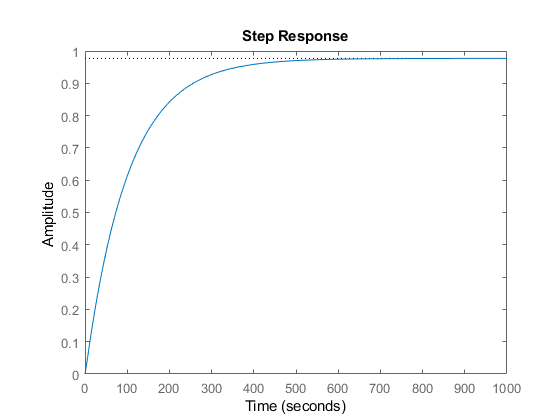


[num, den] = pade(0.7, 3);

G_plant = G_plant * tf(num, den);

H = 1;

G = G_plant * H;

step(feedback(G, 1))

stepinfo(feedback(G,1))

ans = struct with fields:
        RiseTime: 221.2980
    SettlingTime: 394.7418
     SettlingMin: 0.8832
     SettlingMax: 0.9771
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9771
        PeakTime: 1.0622e+03


21 - 16 * 0.9722

ans = 5.4448

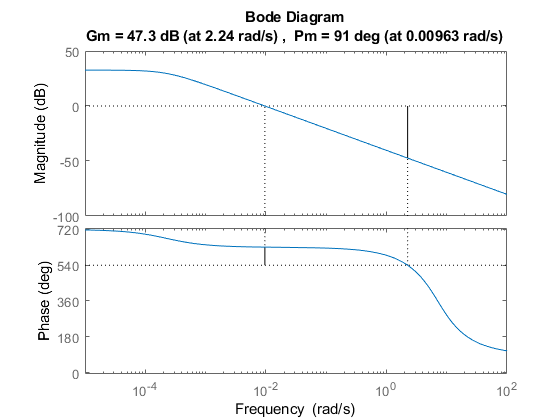

margin(G_plant)